# **GaussCL**

Lemniscate cosine function

## Definition


$$\mathrm{cl}\phi =\mathrm{cos}\;\textrm{lemn}\;\phi \equiv \mathrm{cn}\left(\phi \sqrt{2},1/\sqrt{2}\right)/\sqrt{2}$$


where *cn* is Jacobi elliptic function ([1]).

Domain: $-\infty <\phi <\infty$. For the specified domain, the  codomain is the set of real numbers.

Special values:

   
$$\mathrm{cl}\left(0\right)=1$$


Identities:


$${\mathrm{sl}}^2 \phi =\frac{1-{\mathrm{cl}}^2 \phi }{1+{\mathrm{cl}}^2 \phi }$$


$\textrm{sl}\phi =\textrm{cl}\left(\frac{\varpi }{2}-\phi \right)$,   $\frac{\varpi }{2}\equiv \int_0^1 \frac{\textrm{dt}}{\sqrt{1-t^4 }}$

## Syntax

Y = GaussCL(PHI)

y = gcl(phi)

## Description

**Y = GaussCL(PHI)** returns the value of the lemniscate cosine function $\mathrm{cl}\phi$ for each element of the array  PHI .  PHI must be real array or scalar. **GaussCL** is the wrapper function which calls the functions **gcl** element-wise via the function **ufun1**.

**y = gcl(phi)** returns the value of the  the lemniscate cosine function $\mathrm{cl}\phi$ for the  phi. It is assumed that  phi is real scalars without check. y is NaN if phi is invalid or convergence failed. **gcl** is the wrapper function which calls the function **gslcl**.

 **gslcl **simultaneously  compute $\mathrm{cl}\phi$ and $\textrm{sl}\phi$ using function **sncndn ** ([2])

## Precision

## **Numerical Examples**

**Scalar input**

format long
phi = pi/2; 
[gcl(phi), GaussCL(phi)]

ans =   -0.259649310926969  -0.259649310926969


Accuracy. 

fprintf('%.16g\n',gcl(1)) 

0.310737930333856


% Maple 0.310737930333856 229

Calculation of the first lemniscate constant (half period)

L = fzero(@(xx)gcl(xx),1);
fprintf('%.16g\n',L)

1.31102877714606


disp(2*L-sqrt(2)/4/sqrt(pi)*gamma(1/4)^2) % check

    -8.881784197001252e-16



phi=200;
disp(gsl(phi)-gcl(L-phi))

    -1.021405182655144e-14



Special values

gcl(0)

ans = 1

Identities

phi = pi/4;
disp(gsl(phi)^2-(1- gcl(phi)^2)/(1 + gcl(phi)^2))

    -2.220446049250313e-16



**Vector input**

phi=[1e-6 2 3 1e20];
disp(GaussSL(phi).^2-(1- GaussCL(phi).^2)./(1 + GaussCL(phi).^2))

   1.0e-16 *

  -0.889005833412821  -0.555111512312578  -0.555111512312578                   0



**Matrix input**

phi=[-1/2 1/3 1/4; 1/2 -1/3 -1/4];
disp(GaussSL(phi).^2-(1- GaussCL(phi).^2)./(1 + GaussCL(phi).^2))

   1.0e-15 *

   0.083266726846887  -0.055511151231258  -0.131838984174237
   0.083266726846887  -0.055511151231258  -0.131838984174237



## **Plot**

**Example 1**

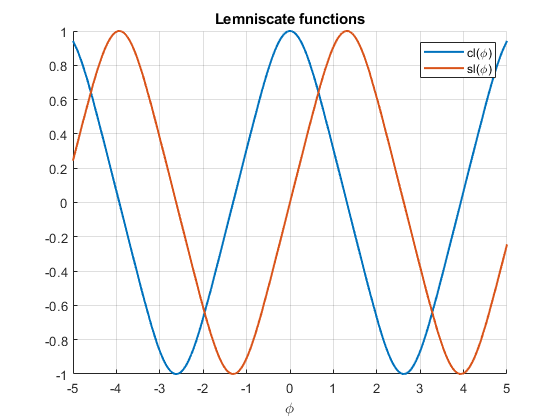

figure
hold on
fplot(@(phi) GaussCL(phi),'LineWidth',1.5)
fplot(@(phi) GaussSL(phi),'LineWidth',1.5)
title('Lemniscate functions')
legend('cl(\phi)','sl(\phi)')
xlabel('\phi')
grid on

**Example 2**

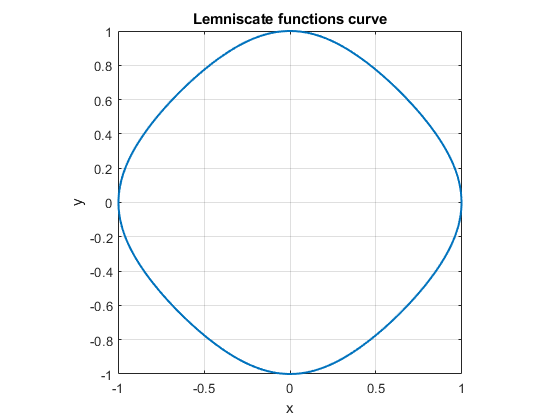

figure
fplot( @(phi) GaussCL(phi), @(phi) GaussSL(phi),'LineWidth',1.5)
title('Lemniscate functions curve')
ylabel('y')
xlabel('x')
axis equal
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Lemniscatic elliptic function, Wikipedia](https://en.wikipedia.org/wiki/Lemniscatic_elliptic_function)

[Lemniscate functions, Encyclopedia of Mathematics](https://www.encyclopediaofmath.org/index.php/Lemniscate_functions)

## **References**

[1] E.T. Whittaker, G.N. Watson, A course of modern analysis, 4. ed., Cambridge Univ. Pr., Cambridge, 1996.

[2]  [W.Ehrhardt, The AMath and DMath Special functions, 2016](http://www.wolfgang-ehrhardt.de/specialfunctions.pdf)

## See Also